# Быстрое преобразование Фурье

Чтение аудиофайла - запись колебания струны гитары (220Гц).

[x, fs] = audioread('spectrum_A220.mp3');
sound(x, fs);
x = x(1:2^15);

БПФ и попытка визуализировать спектр:

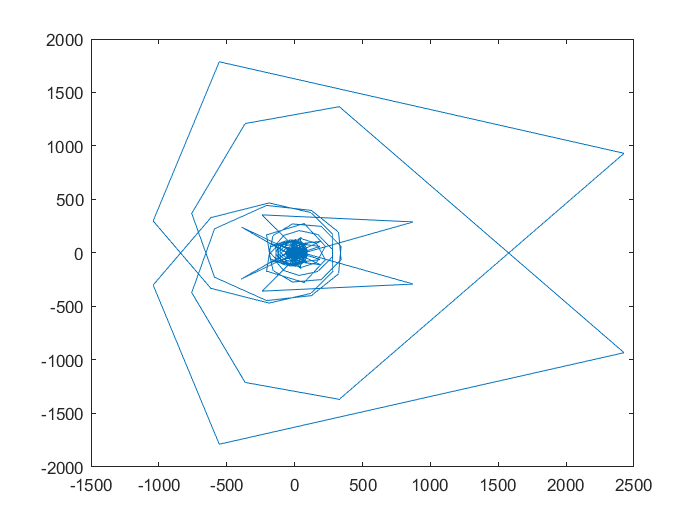

x = fft(x);
plot(x);

Построение амплитудного спектра сигнала:

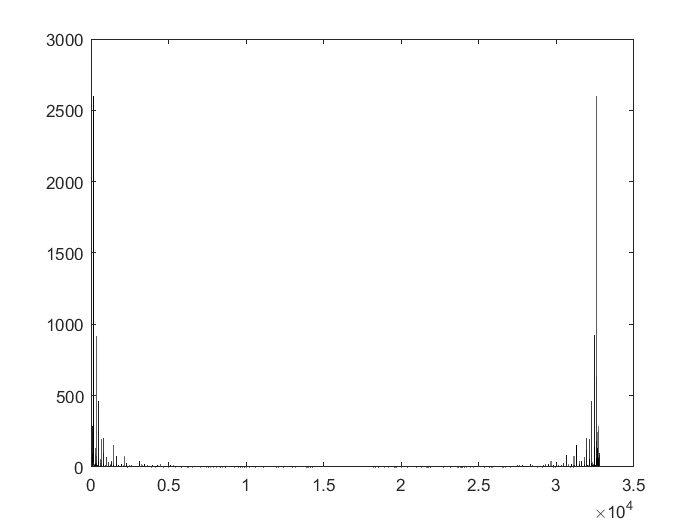

area(abs(x));

Функция **fftshift() **преобразует спектр (выход функции **fft() **и сдвигает отсчёты симметрично нулевой частоты:

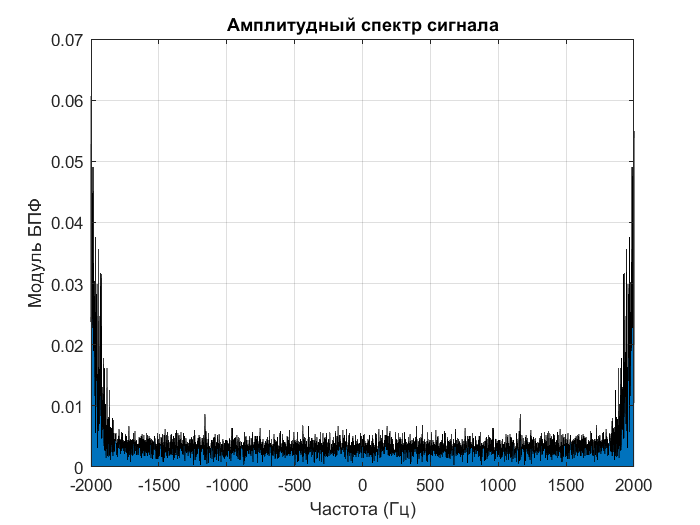

Xshift = fftshift(x);
F = linspace(-fs/2, fs/2, length(x));
area(F, abs(x));
xlim([-2e3 2e3]);
grid on;
title('Амплитудный спектр сигнала');
xlabel('Частота (Гц)');
ylabel('Модуль БПФ');

Спектр в области положительных частот:

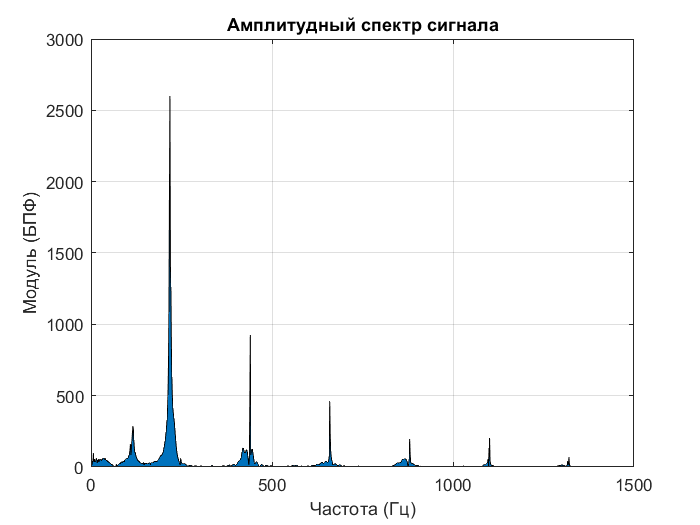

Xpositive = x([1:length(x)/2]);
Fpositive = linspace(0, fs/2, length(Xpositive));
area(Fpositive, abs(Xpositive));
xlim([0 1500]);
grid on;
hold on;
title('Амплитудный спектр сигнала');
xlabel('Частота (Гц)');
ylabel('Модуль (БПФ)');

Нахождение максимумов действительной части спектра:

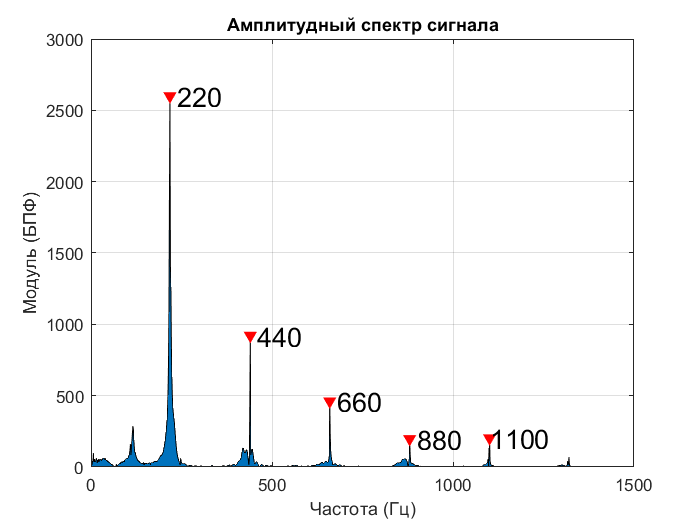

[~, locs] = findpeaks(abs(Xpositive), 'MinPeakHeight', 100, 'MinPeakDistance', 100);
Fpeaks = Fpositive(locs);
plot(Fpeaks, abs(Xpositive(locs)), 'rv', 'MarkerFaceColor', 'r');
cellpeaks = cellstr(num2str(round(Fpeaks', -1)));
text(Fpeaks, abs(Xpositive(locs)), cellpeaks, 'FontSize', 16);
hold off;

Основные частоты нот:

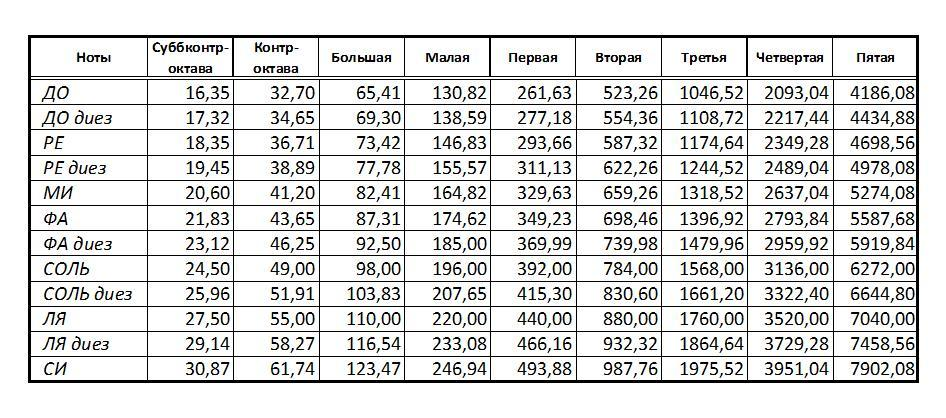

Обратное быстрое преобразование Фурье (ОБПФ) - функция **ifft(x)**:

y = ifft(x);
sound(y, fs);